# Próbkowanie- co to takiego? Po co je wykorzystywać? Jak obliczyć?

Laboratorium zostanie oparte na wczytaniu dźwięku na przestrzeni danych- Workspace'a. Funkcja audioread konwertuje dźwięk mp3 na macierz. W ilu kolumnach zawarty jest dźwięk? Czy jest w więcej niż jednej? Dlaczego? 

Przy funkcji audioread należy podać nazwę dźwięku, i jeśli jest w innym folderze, należy podać do niego ścieżkę. Funkcja audioinfo przechowuje w w zmiennej dzwiekInfo informacje o wybranym dźwięku: czas trwania (duration), co ile występuje próbka dźwięku (Sample Rate)- co jaki czas jest pobierany kolejny dźwięk, oraz całkowita czas trwania wszytskich próbek. 

W jaki sposób można sprawdzić czy czas trwania i całkowity czas trwania dadzą czas trwania jednej próbki? A czy można sprawdzić czy Sample Rate i Total Samples przy odpowiednim obliczeniu "da" Duration?

dzwiek = audioread("Dżwięk uruchamiania Windows 95.mp3");
dzwiekInfo = audioinfo("Dżwięk uruchamiania Windows 95.mp3");
Fs = dzwiekInfo.SampleRate %czas próbkowania

Fs = 44100


% Fscalkowite = dzwiekInfo.TotalSamples
% dura = dzwiekInfo.Duration
% 
% spr = Fscalkowite * (1/Fs)

Czas jednej próbki jest podany w Hz, aby obliczyć czas jednej próbki w sekundach należy podzielić 1s przez czas jednej próbki.

czas = 1; %s
czasFs = czas/Fs;

Gdy wykonamy wykres dla dźwięku, na osi x będzie podany numer porządkowy próbki. Jeśli cała macierz zawiera w jednej kolumnie 313968 wierszy, wóczas taka liczba będzie wartościa maksymalną na wykresie dźwięku:

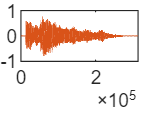

plot(dzwiek)

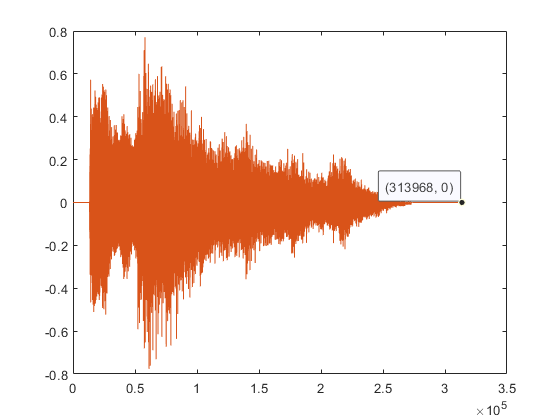

A co jeśli chcemy, aby zamienić numer porządkowy odpowiadajacy na czas trwania dźwięku? Wówczas musimy znać:

- liczbę wierszy w kolumnie 1 (należy uważać, aby nie brać obu kolumn pod uwagę!!)

- czas maksymalny, który można obliczyć poprzez mnożenie czasu próbkowania (czasFs) przez liczbę wierszy w pierwszej kolumnie

Wówczas możemy obliczyć czas wykorzystując funkcję linspace:

- znamy zakres od 0 do czasu maksymalnego

- znamy ile ma być wierszy w zmiennej czas (musi być ich dokładnie tyle ile wynosi liczba wierszy w pierwszej kolumnie)

[rowDzwiek, colDzwiek] = size(dzwiek);
czasMax = czasFs * rowDzwiek;
czasDzwiek(:,1) = linspace(0, czasMax, rowDzwiek);

Mając zmienną czas oraz dźwięk można wygenerować wykres dźwięku dla pierwszej, drugiej, bądź obu kolumn

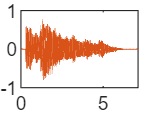

plot(czasDzwiek, dzwiek)

Obecne zadanie polega na "wycięciu" framgemntu dźwięku. Zakładamy wartość minimalną oraz maksymalną dźwięku, które mają być interesujacym nas zakresem dźwięku.

przedzialMin = -0.1;
przedzialMax = 0.2;

Wykorzystując funkcję find znajdujemy wartości dźwięku dla kolumny 1 z zakresu objętego przez przedziałMin oraz przedziałMax. Funkcja find zwraca indeks, a nie wartość, dlatego...

dzwiekPrzedzialIdx = find(dzwiek(:,1) >= przedzialMin & ...
 dzwiek(:,1) <= przedzialMax);

należy znaleźć wartości dźwięku z odpowiadającymi im indeksmai wierszy.

dzwiekPrzedzialVal = dzwiek(dzwiekPrzedzialIdx);

liczba wierszy jest mniejsza niż przy oryginalnym dźwięku, dlatego należy ponownie obliczyć czas maksymalny trwania dźwięku oraz zmienną, która będzie przechowywać wartości czasu dla poszczególnych próbek. Czas próbkowania nie uległ zmianie.

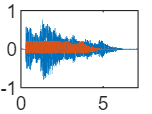

[rowPrzedzial, colPrzedzial] = size(dzwiekPrzedzialVal);
czasPrzedzialMax = czasFs * rowPrzedzial;
czasPrz(:,1) = linspace(0, czasPrzedzialMax, rowPrzedzial);
figure(8)
plot(czasDzwiek, dzwiek(:,1), czasPrz,dzwiekPrzedzialVal )

W jaki sposób można pozbyć się wartości 0 z początku?

Najpierw sprawdzamy indeksy wierszy, w których występują wartości 0 poprzez funkcję find (wykonujemy tę operację dla pierwszej kolumny!). Następnie sprawdzamy rozmiar pwstałej macierz, zawierającej numery indeksów.

dzwiek0Idx = find(dzwiek(:,1) == 0);
dzwiek0Size = size(dzwiek0Idx);

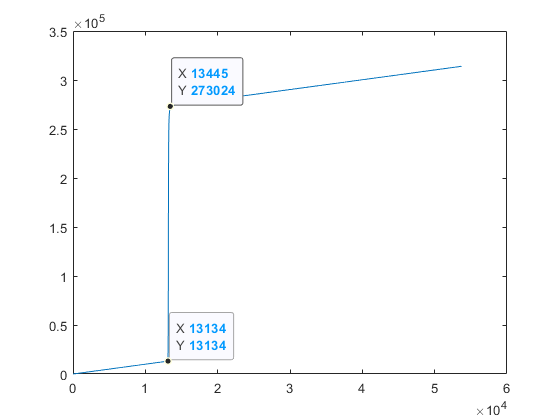

Kolejnym krokiem jest obliczenie różnicy pomiędzy kolejnymi wierszami, począwszy od 1 do przedostatniego wiersza. 

for i =1:dzwiek0Size(1,1)-1
    roznica(i,1) = dzwiek0Idx(i+1,1)-dzwiek0Idx(i,1);
end

Następnie wyszukujemy indeksy wierszy w zmiennej różnica, gdzie wystąpiła wartość różnicy większa niż 1. Pierwsy element, którego różnica wynosi więcej niż 1, został przyjęty jako osoatni element zawierający 0.

roznicaIdxFind = find(roznica>1)

roznicaIdxFind =        13152
       13153
       13154
       13155
       13156
       13157
       13159
       13160
       13161
       13162


roznicaIdx = roznicaIdxFind(1,1)

roznicaIdx = 13152

następnym krokiem jest zapisanie dzwięku bez wartości 0 od indesu o jeden większego od pierwszego elementu różnicaIdx do końca pliku.

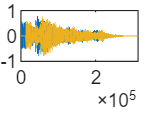

dzwiekBez0(:,1) = dzwiek(roznicaIdx+1:end,1);
plot(dzwiekBez0)
hold on
plot(dzwiek)
hold off

# Usuwanie nieprawidłowych wartości pomiarowych

Usuwanie nieprawidłowych wartości można zapewne wykonać na kilka sposobów. Poniżej zostały przedstawione dwa z nich.

- Za pomocą funkcji find, pętli for i instrukcji if.

- Za pomocą funkcji ismissing oraz find i pętli for

#### Za pomocą funkcji find, pętli for i instrukcji if

wczytuje "swój" zestaw do zmiennej asia. Sprawdzam prze funkcję maxk pięć największych wartości w zmiennej asia w drugim wierszu. Sprawdzam rozmiar macierzy asia. 

Dla wszystkich elementów macierzy asia sprawdzam czy dany wiersz w drugiej kolumnie ma wartość większą od wartości przechowywanej w asiaMax - 300. Jeśli to prawda, to do tego wiersza przypisywana jest wartość z wiersza poprzedniego, jeśli fałsz, wiersz pozostaje bez zmian.

asia= zestaw1{1,1}(:,:);
asiaMax = maxk(asia(:,2),5)

asiaMax = 	1.0e+03 *

    0.0096    1.0000    0.0150    0.0013    0.0002    0.0510    0.0600    0.6820    0.0482    0.0383    0.0003
    0.0095    1.0000    0.0150    0.0012    0.0002    0.0510    0.0600    0.6820    0.0452    0.0342    0.0002
    0.0094    1.0000    0.0132    0.0012    0.0002    0.0510    0.0600    0.6820    0.0405    0.0339    0.0002
    0.0094    1.0000    0.0103    0.0012    0.0002    0.0510    0.0600    0.6820    0.0405    0.0333    0.0002
    0.0093    1.0000    0.0094    0.0012    0.0002    0.0510    0.0600    0.6770    0.0359    0.0327    0.0002


asiaSize = size(asia)

for i =1:asiaSize(1,1)
    if asia(i,2) >(asiaMax(1,1)- 300)

asiaFindMissing =     10
    28
    45
    63
    80
    98
   115
   133
   150
   168


        asia(i,2) = asia(i-1,2);
    else

sizeFindMis =     10     1


        asia(i,2)= asia(i,2);
    end
end

#### Za pomocą funkcji ismissing oraz find i pętli for

Ponownie wczytuję swój zestaw do zmiennej asia. Sprawdzam 5 największych wartości w każdej kolumnie. Następnie zapisuje wartość, która jest nieprawidłowa- widać, że w drugiej kolumnie występuje wartość 1000, która znacznie przewyższa pozostałe wiersze w drugiej kolumnie. Podaję funkjci ismissing, że w macierzy asia, występuje wartość nieprawidłowa, która jest zapisana pod zmienną asiaMissingVal.

Funkcja ismissing sprawdza czy w którymś wierszu w zmiennej wystapiły "zakazane" - nieprawidłowe wartości. Ismissing przyjmuje wartość 1, jeśli wystąpi nieprawidłowa (podana jako parametr) wartość.

asia= zestaw1{1,1}(:,:);
asiaMax = maxk(asia, 5)
asiaMissingVal = asiaMax(1,2);
asiaZestawMissing = ismissing(asia, asiaMissingVal);

licznik = 9

licznik = 27

licznik = 44

licznik = 62

licznik = 79

licznik = 97

licznik = 114

licznik = 132

licznik = 149

licznik = 167

Za pomocą funkcji find następuje szukanie w których wierszach w drugiej kolumnie wystąpiły "1".

asiaFindMissing(:,1) = find(asiaZestawMissing(:,2)==1)

Sprawdzenie rozmiaru macierzy z indeksami nieprawidłowych wartości- asiaFindMissing

sizeFindMis = size(asiaFindMissing)

Aby nie przeszukiwać całej macierzy asia, zdecydowano się, że zostaną wykorzystane indeksy, gdzie wystąpiły nieprawidłowe wartości. Zapis:


$$\textrm{asia}\left(\textrm{asiaFindMissing}\left(i,1\right),2\right)=\textrm{asia}\left(\textrm{licznik},2\right)$$


oznacza, że bierze się kolejne indeksy wartości "zepsutych" w macierzy asia w 2 kolumnie i przypisuje się im wartości z wiersza poprzedniego. Zmienna licznik została dodana pomocniczo, aby zapisywać w niej wartości poprawne o jeden wiersz niżej niż wartość zepsuta.

for i=1:sizeFindMis(1,1)
    licznik = asiaFindMissing(i,1)-1
    asia(asiaFindMissing(i,1),2) = asia(licznik,2);
end

# Podobieństwo sygnałów

#### Wtęp

open my_figure.m

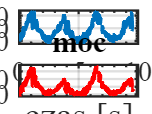


t = asia(:,1);
moc = asia(:,10);

sila = asia(:,2);
[N, nn] = size(sila);

m_cov = 	1.0e+03 *

    1.0736    0.2851
    0.2851    0.0828


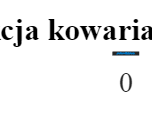

N = size(sila);
N(1,1)
figure; subplot(211); plot(t, asia(:,2), 'LineWidth', 2); 
my_figure('czas [s]', 'F_n [mN]', 'Siła z tensometrów'); grid on;
subplot(212); plot(t, asia(:,10), 'r', 'LineWidth', 2);
my_figure('czas [s]', 'P [mW]', 'moc'); grid on;

#### Współczynnik kowariancji

m_cov = cov(sila,moc)

m_kor =     1.0000    0.9566
    0.9566    1.0000


#### Funkcja kowariancji

[f_cov, lags] = xcov(sila, moc, 'unbiased',N/2);
tal=lags*dt;
figure; plot(tal, f_cov, 'LineWidth', 2); 
my_figure('Tal [min]', 'Cxy', 'Funkcja kowariancji siła-moc');
grid on;

#### Współczynnik korelacji

m_kor = corrcoef(sila, moc)

#### Funkcja korelacji

[f_kor_raw, lags] = xcorr(sila, moc, 'unbiased', N/2);
figure; subplot(211);
plot(tal, f_kor_raw, 'LineWidth', 2);
my_figure('Tal [min]', 'Rxy raw', 'Funkcja korelacji siła-moc');

#### Unormowana funkcja korelacji

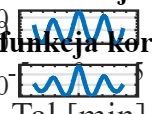

[f_kor_norm, lags] = xcorr(sila - mean(sila), moc - mean(moc), 'coef', N/2);

tal=lags*dt;
subplot(212)
plot(tal, f_kor_norm, 'LineWidth', 2); 
my_figure('Tal [min]', 'Rxy', 'Unormowana funkcja korelacji siła- moc');
grid on;